# Experiment 7.1

## Name: 

## Objectives

To verify the effect of input waveform, loop gain, and system type upon steady-state errors.

### Minimum Required Software Packages

MATLAB, Simulink, and the Control System Toolbox.

## Prelab

For the Prelab of this experiment, here is some code to generate the responses of the system-types to the multiple inputs. You don not need to replicate this on your own, but feel free to use any of the code to make your own documents or figures look more interesting. 

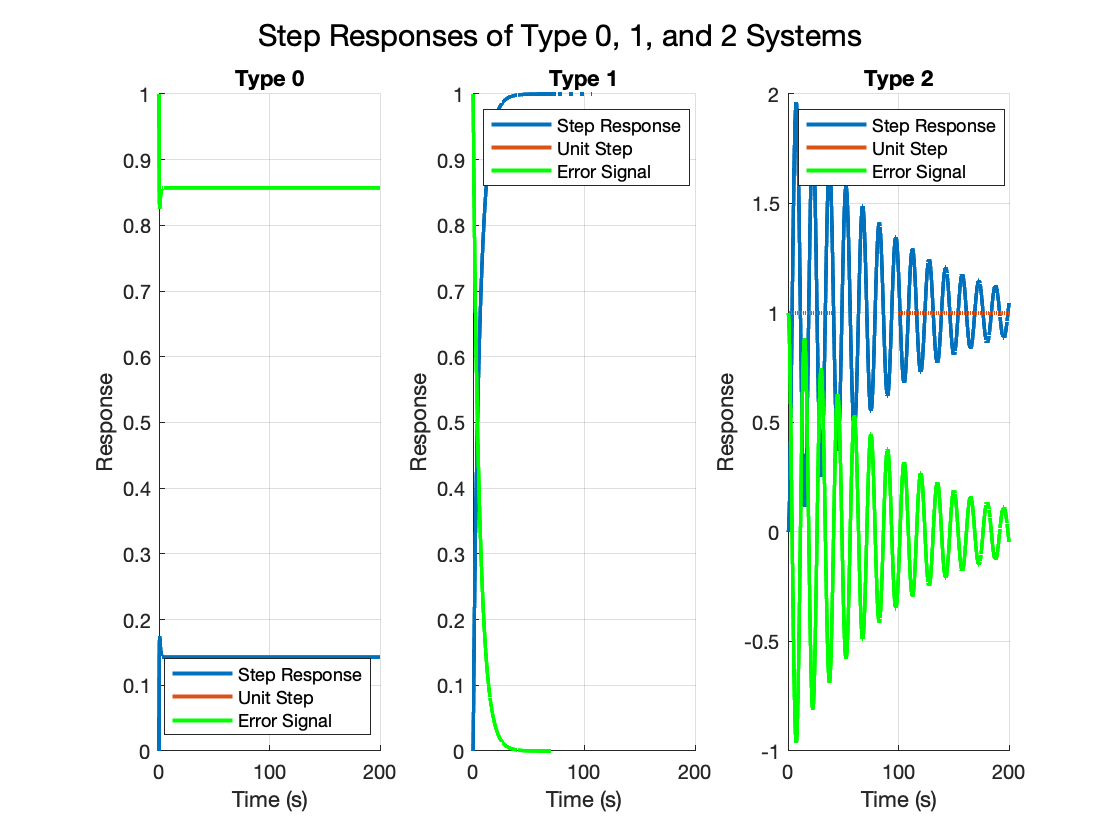

G = tf([1 1],[1 5 6]);           % Simple Second Order System

G_type0 = feedback(G, 1);                   % Unity Feedback System for Type 0
G_type1 = feedback(G*tf([1],[1 0]), 1);     % Unity Feedback System for Type 1
G_type2 = feedback(G*tf([1],[1 0 0]), 1);   % Unity Feedback System for Type 2

EndTime = 200;        % Simulation Time, set to 10 and work from there

SimTime = 0:0.01:EndTime;            % Generate Time Base for simulations

% Gather Step Responses
[StepG0, SimTime] = step(G_type0, SimTime);   % Type 0
[StepG1, SimTime] = step(G_type1, SimTime);   % Type 1           
[StepG2, SimTime] = step(G_type2, SimTime);   % Type 2           

% Normalize the data to the final value for possible plots
StepG0Norm = StepG0 ./ StepG0(length(StepG0));  
StepG1Norm = StepG1 ./ StepG1(length(StepG1));  
StepG2Norm = StepG2 ./ StepG2(length(StepG2));  

unitstep = (SimTime>=0);            % Generate Unit-Step Input Signal

StepErrorG0 = unitstep - StepG0;    % Calculate Step Error Signal for Type 0 System
StepErrorG1 = unitstep - StepG1;    % Calculate Step Error Signal for Type 1 System
StepErrorG2 = unitstep - StepG2;    % Calculate Step Error Signal for Type 2 System

ramp = SimTime.*unitstep;           % Generate Ramp Input Signal

RampG0 = lsim(G_type0, ramp, SimTime);  % Generate Ramp Response for Type 0 System
RampG1 = lsim(G_type1, ramp, SimTime);  % Generate Ramp Response for Type 1 System
RampG2 = lsim(G_type2, ramp, SimTime);  % Generate Ramp Response for Type 2 System

RampErrorG0 = ramp - RampG0;        % Calculate Ramp Error Signal for Type 0 System
RampErrorG1 = ramp - RampG1;        % Calculate Ramp Error Signal for Type 1 System
RampErrorG2 = ramp - RampG2;        % Calculate Ramp Error Signal for Type 2 System

parabolic = (SimTime.^2).*unitstep; % Generate Parabolic Input Signal

ParaG0 = lsim(G_type0, parabolic, SimTime); % Generate Parabolic Response for Type 0 System
ParaG1 = lsim(G_type1, parabolic, SimTime); % Generate Parabolic Response for Type 1 System
ParaG2 = lsim(G_type2, parabolic, SimTime); % Generate Parabolic Respsone for Type 2 System

ParaErrorG0 = parabolic - ParaG0;   % Calculate Parabolic Error Signal for Type 0 System
ParaErrorG1 = parabolic - ParaG1;   % Calculate Parabolic Error Signal for Type 1 System
ParaErrorG2 = parabolic - ParaG2;   % Calculate Parabolic Error Signal for Type 0 System



PlotLineWidth = 2;  % Used to set linewidth for all plots

figureHandleStepIndividual = figure();                  % Establish a new figure and save its figure handle
sgtitle("Step Responses of Type 0, 1, and 2 Systems")
subplot(1, 3, 1)                                        % Begin Step Response Subplot
    hold on
    plot(SimTime, StepG0, "lineWidth", PlotLineWidth)                   % Plot Step Response for Type 0
    plot(SimTime, unitstep, "lineWidth", PlotLineWidth)                 % Plot Unit Step
    plot(SimTime, StepErrorG0, "linewidth", PlotLineWidth, 'Color', 'g')% Plot Error Signal
    title("Type 0")
    grid on
    xlabel("Time (s)")
    ylabel("Response")
    hold off
    legend(["Step Response", "Unit Step", "Error Signal"], "Location", "south")
subplot(1, 3, 2)
    hold on
    plot(SimTime, StepG1, "lineWidth", PlotLineWidth)                   % Plot Step Response for Type 1
    plot(SimTime, unitstep, "lineWidth", PlotLineWidth)                 % Plot Unit Step
    plot(SimTime, StepErrorG1, "linewidth", PlotLineWidth, 'Color', 'g')% Plot Error Signal
    title("Type 1")
    grid on
    xlabel("Time (s)")
    ylabel("Response")
    hold off
    legend(["Step Response", "Unit Step", "Error Signal"], "Location", "northwest")
subplot(1, 3, 3)
    hold on
    plot(SimTime, StepG2, "lineWidth", PlotLineWidth)                   % Plot Step Response for Type 2
    plot(SimTime, unitstep, "lineWidth", PlotLineWidth)                 % Plot Unit Step
    plot(SimTime, StepErrorG2, "linewidth", PlotLineWidth, 'Color', 'g')% Plot Error Signal
    title("Type 2")
    grid on
    xlabel("Time (s)")
    ylabel("Response")
    hold off
    legend(["Step Response", "Unit Step", "Error Signal"], "Location", "northwest")

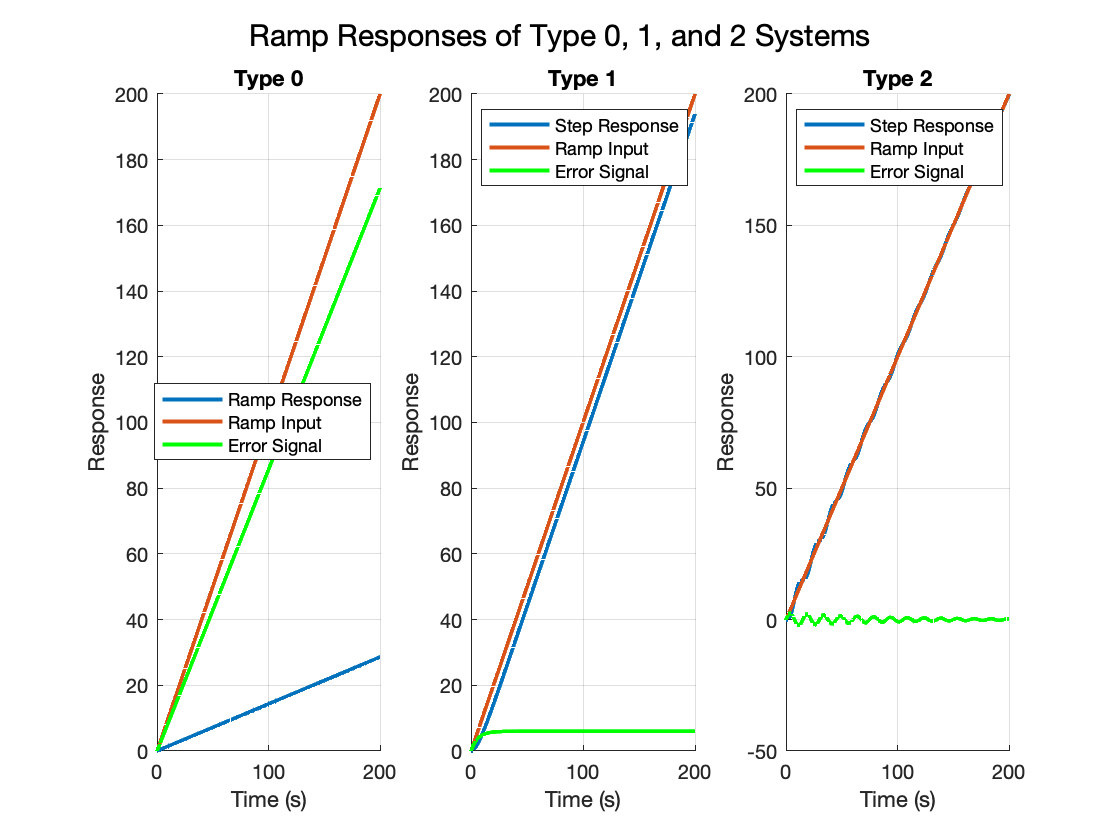

figureHandleRamp = figure();
sgtitle("Ramp Responses of Type 0, 1, and 2 Systems")
subplot(1, 3, 1)                                        % Begin Ramp Response Subplot
    hold on
    plot(SimTime, RampG0, "lineWidth", PlotLineWidth)                   % Plot Ramp Response for Type 0
    plot(SimTime, ramp, "lineWidth", PlotLineWidth)                     % Plot Ramp Signal
    plot(SimTime, RampErrorG0, "linewidth", PlotLineWidth, 'Color', 'g')% Plot Error Signal
    title("Type 0")
    grid on
    xlabel("Time (s)")
    ylabel("Response")
    hold off
    legend(["Ramp Response", "Ramp Input", "Error Signal"], "Location", "east")
subplot(1, 3, 2)
    hold on
    plot(SimTime, RampG1, "lineWidth", PlotLineWidth)                   % Plot Ramp Response for Type 1
    plot(SimTime, ramp, "lineWidth", PlotLineWidth)                     % Plot Ramp Signal
    plot(SimTime, RampErrorG1, "linewidth", PlotLineWidth, 'Color', 'g')% Plot Error Signal
    title("Type 1")
    grid on
    xlabel("Time (s)")
    ylabel("Response")
    hold off
    legend(["Step Response", "Ramp Input", "Error Signal"], "Location", "northwest")
subplot(1, 3, 3)
    hold on
    plot(SimTime, RampG2, "lineWidth", PlotLineWidth)                   % Plot Ramp Response for Type 2
    plot(SimTime, ramp, "lineWidth", PlotLineWidth)                     % Plot Ramp Signal
    plot(SimTime, RampErrorG2, "linewidth", PlotLineWidth, 'Color', 'g')% Plot Error Signal
    title("Type 2")
    grid on
    xlabel("Time (s)")
    ylabel("Response")
    hold off
    legend(["Step Response", "Ramp Input", "Error Signal"], "Location", "northwest")

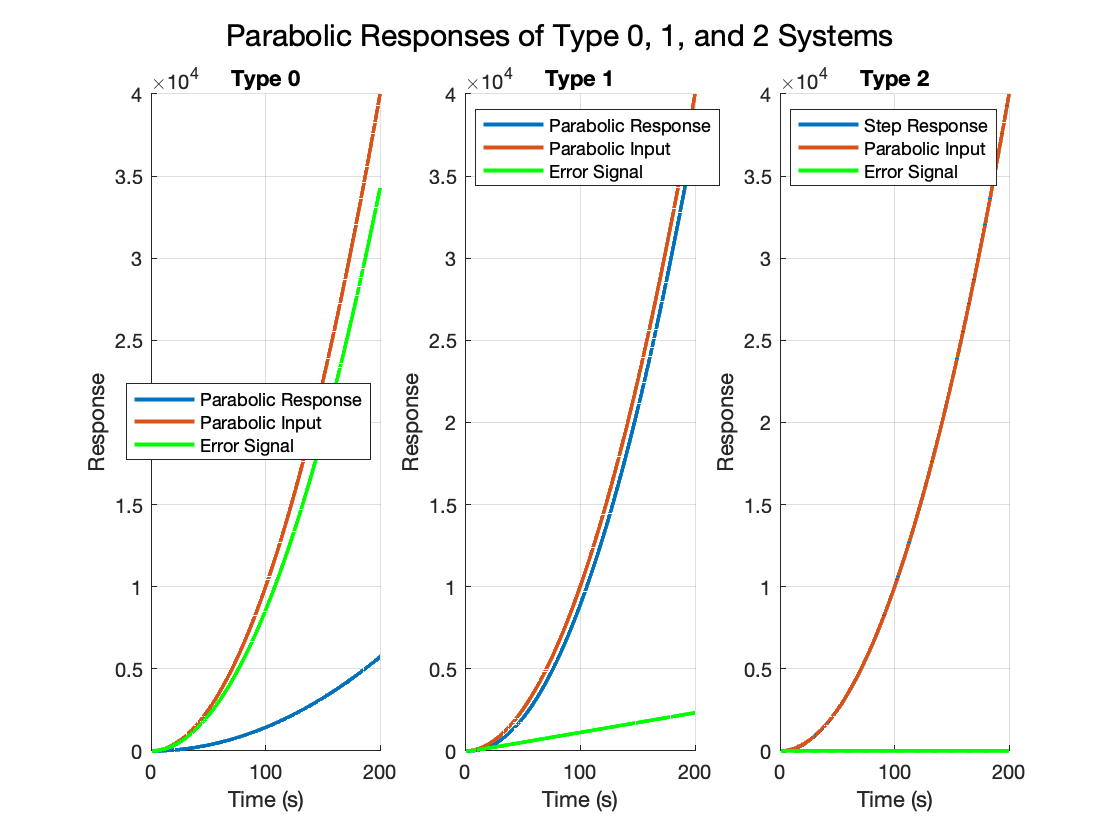

figureHandlePara = figure();
sgtitle("Parabolic Responses of Type 0, 1, and 2 Systems")
subplot(1, 3, 1)                                                        % Begin Parabolic Response Subplot
    hold on
    plot(SimTime, ParaG0, "lineWidth", PlotLineWidth)                   % Plot Parabolic Response for Type 0
    plot(SimTime, parabolic, "lineWidth", PlotLineWidth)                % Plot Parabolic Signal
    plot(SimTime, ParaErrorG0, "linewidth", PlotLineWidth, 'Color', 'g')% Plot Error Signal
    title("Type 0")
    grid on
    xlabel("Time (s)")
    ylabel("Response")
    hold off
    legend(["Parabolic Response", "Parabolic Input", "Error Signal"], "Location", "east")
subplot(1, 3, 2)
    hold on
    plot(SimTime, ParaG1, "lineWidth", PlotLineWidth)                   % Plot Parabolic Response for Type 1
    plot(SimTime, parabolic, "lineWidth", PlotLineWidth)                % Plot Parabolic Signal
    plot(SimTime, ParaErrorG1, "linewidth", PlotLineWidth, 'Color', 'g')% Plot Error Signal
    title("Type 1")
    grid on
    xlabel("Time (s)")
    ylabel("Response")
    hold off
    legend(["Parabolic Response", "Parabolic Input", "Error Signal"], "Location", "northwest")
subplot(1, 3, 3)
    hold on
    plot(SimTime, ParaG2, "lineWidth", PlotLineWidth)                   % Plot Parabolic Response for Type 2
    plot(SimTime, parabolic, "lineWidth", PlotLineWidth)                % Plot Parabolic Signal
    plot(SimTime, ParaErrorG2, "linewidth", PlotLineWidth, 'Color', 'g')% Plot Error Signal
    title("Type 2")
    grid on
    xlabel("Time (s)")
    ylabel("Response")
    hold off
    legend(["Step Response", "Parabolic Input", "Error Signal"], "Location", "northwest")

### Problem 1

*What system types will yield zero steady-state error for step inputs?*

**Answer:**

### Problem 2

*What system types will yield zero steady-state error for ramp inputs?*

**Answer:**

### Problem 3

*What system types will yield infinite steady-state error for ramp inputs?*

**Answer:**

### Problem 4

*What system types will yield zero steady-state error for parabolic inputs?*

**Answer:**

### Problem 5

*What system types will yield infinite steady-state error for parabolic inputs?*

**Answer:**

### Problem 6

*For the negative feedback system of Figure P6.19 where*$G(s) = \frac{K(s+6)}{(s+4)(s+7)(s+9)(s+12)}$ and $H(s) = 1$, calculate the steady-state error in terms of $K$ for the following inputs: $5u(t)$, $5tu(t)$, and $5t^2u(t)$. 

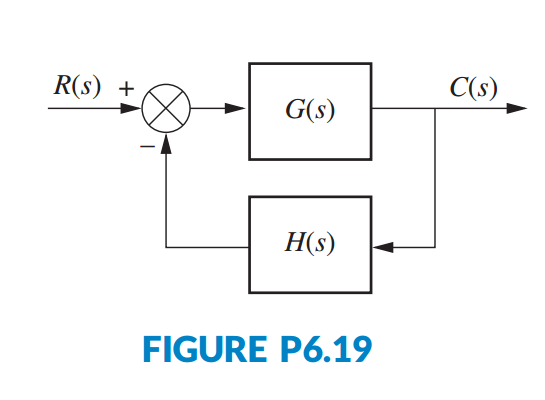

**Answer:**

### Problem 7

*Repeat Prelab 6 for *$G(s) = \frac{K(s+6)(s+8)}{s(s+4)(s+7)(s+9)(s+12)}$ and $H(s) = 1$.

**Answer:**

### Problem 8

*Repeat Prelab 6 for *$G(s) = \frac{K(s+1)(s+6)(s+8)}{s^2(s+4)(s+7)(s+9)(s+12)}$ and $H(s) = 1$.

**Answer:**

## Lab

### Problem 1

*Using Simulink, set up the negative feedback system of Prelab 6. Plot on one graph the error signal of the system for an input of *$5u(t)$ and $K$=50, 500, 1000, and 5000. Repeat for inputs of $5tu(t)$ and $5t^2u(t)$.

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

% Insert your code here

### Problem 2

*Using Simulink, set up the negative feedback system of Prelab 7. Plot on one graph the error signal of the system for an input of *$5u(t)$ and $K$=50, 500, 1000, and 5000. Repeat for inputs of $5tu(t)$ and $5t^2u(t)$.

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

% Insert your code here

### Problem 3

*Using Simulink, set up the negative feedback system of Prelab 8. Plot on one graph the error signal of the system for an input of *$5u(t)$ and $K$= 200, 400, 800, and 1000. Repeat for inputs of $5tu(t)$ and $5t^2u(t)$.

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

% Insert your code here

## Postlab

### Problem 1

*Use your plots from Lab 1 and compare the expected steady-state errors to those calculated in the Prelab. Explain the reasons for any discrepancies.*

### Problem 2

*Use your plots from Lab 2 and compare the expected steady-state errors to those calculated in the Prelab. Explain the reasons for any discrepancies.*

### Problem 3

*Use your plots from Lab 3 and compare the expected steady-state errors to those calculated in the Prelab. Explain the reasons for any discrepancies.*